# Max's Analysis Script

## Load Necessary Saved Data

clear; clc; close all;
try
    loadData = load("C:\Users\maxcr\OneDrive\Class Materials\ASML Capstone\ASML_Code\Saved_Runs\ASML_EC_Sim_Run_zeroShot_13_Jan_2023_15_40_1.mat");
catch
  [fname,fpath] = uigetfile('C:\Users\maxcr\OneDrive\Class Materials\ASML Capstone\ASML_Code\Saved_Runs\','Select a dataset');
  loadData = load(fullfile(fpath,fname));
  disp(['Selected ', fullfile(fpath,fname)]);
end

Selected C:\Users\maxcr\OneDrive\Class Materials\ASML Capstone\ASML_Code\Saved_Runs\ASML_EC_Sim_Run_zeroShot_17_Jan_2023_21_47_14.mat


logsout = loadData.logsout;
ec = loadData.ec;
clear loadData fpath fname;

**WARNING: Much of the provided data will have ECdriveLaserGainCommand < 1. You **

**should only extract OL EUV data where ECdriveLaserGainCommand == 1, unless you have a special need for that lower energy data, e.g., ID of the transfer function from gain command to EUV.**

Ts = 20e-6; % nominal 50kHz sample rate
% generate a time vector equal to the length of the data vector
t = Ts*(1:length(ec.ECeuvValue))'-Ts;
% set the open-loop EUV and enab signal as inputs:
enab = ec.ECeuvValue > 1; % not terribly robust; exercise for the reader

## Energy Data Available for Control Purposes

Extract data arrays for EUV = ON (enab = 1) portions of the data. Do this for both open loop and closed loop energy for scanner/reticle energy and internal source energy.

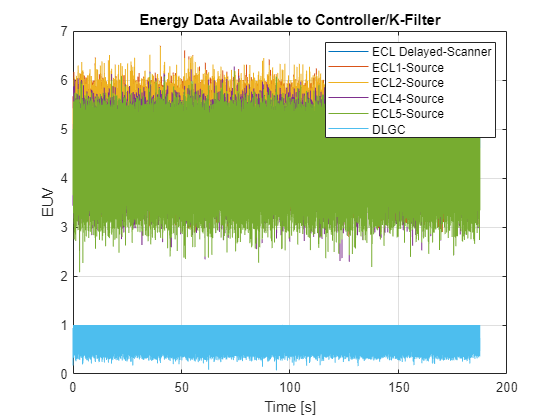

relidx = (logsout.enab == 1); %logical array - ideally just when the system is up and running
X = 1e3; Y = 1e2;
relidx = mod_relidx(relidx,X,Y);
figure;
plot(logsout.T_Ecl_Scanner_Delayed(relidx),logsout.Ecl_Scanner_Delayed(relidx)); hold on; grid on;
plot(logsout.T_Ecl_Source1(relidx),logsout.Ecl_Source1(relidx));
plot(logsout.T_Ecl_Source2(relidx),logsout.Ecl_Source2(relidx));
plot(logsout.T_Ecl_Source4(relidx),logsout.Ecl_Source4(relidx));
plot(logsout.T_Ecl_Source5(relidx),logsout.Ecl_Source5(relidx));
plot(logsout.T_dlgc(relidx),logsout.dlgc(relidx));
xlabel('Time [s]'); ylabel('EUV');
title('Energy Data Available to Controller/K-Filter')
 legend('ECL Delayed-Scanner','ECL1-Source','ECL2-Source','ECL4-Source','ECL5-Source','DLGC');

## n4sid Setup

Need to improve the input/output data so its just for the middle of a run, weird stuff (1s and 0s) are currently messing with hte n4sid model.

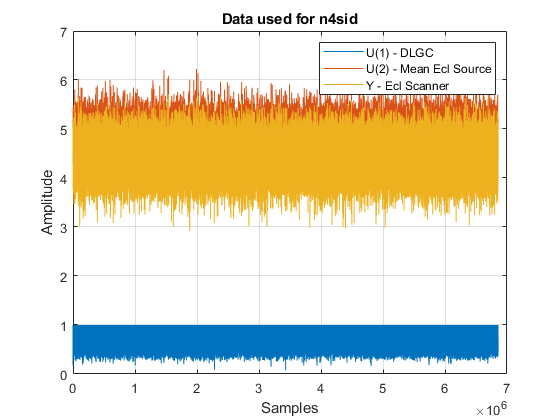

% u = [logsout.dlgc(relidx), logsout.Ecl_Source1(relidx), logsout.Ecl_Source2(relidx), logsout.Ecl_Source4(relidx), logsout.Ecl_Source5(relidx)];
% y = [logsout.Ecl_Scanner(relidx)];
 %data = iddata(y,u,Ts);

 Ecl_Sources = [logsout.Ecl_Source1(relidx), logsout.Ecl_Source2(relidx), logsout.Ecl_Source4(relidx), logsout.Ecl_Source5(relidx)];
 Ecl_Source_Mean = mean(Ecl_Sources,2);
 u = [logsout.dlgc(relidx), Ecl_Source_Mean];
 y = [logsout.Ecl_Scanner(relidx)];
 data = iddata(y,u,Ts);

figure; plot(u(:,1)); hold on; plot(u(:,2)); grid on; plot(y);
xlabel('Samples'); ylabel('Amplitude'); title('Data used for n4sid');
legend('U(1) - DLGC', 'U(2) - Mean Ecl Source', 'Y - Ecl Scanner')

## Perform SysID

 tic
 nx = 4;
 opt = n4sidOptions('EnforceStability',true);
 sys = n4sid(data,nx,'Feedthrough',1,opt); %make sure Feedthrough is enabled
 toc

Elapsed time is 176.526605 seconds.


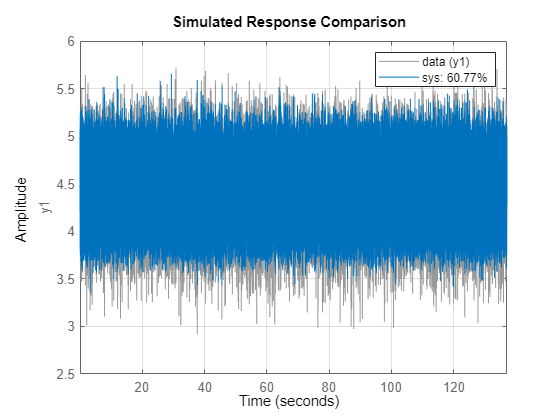

figure;
 compare(data,sys); grid on;

## Simulate SS Model

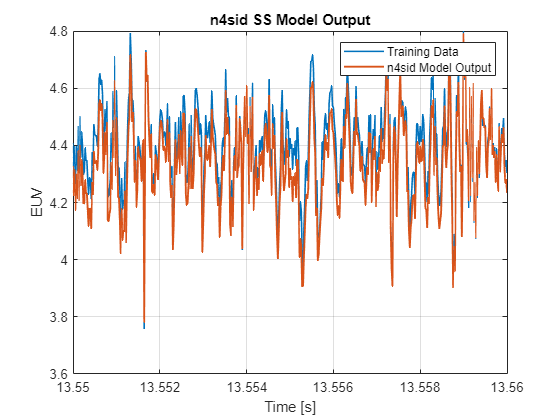

 %load('ssmodel.mat');
 len = size(u);
 smax = len(1);
 t = (0:Ts:((smax-1)*Ts)).';
 ysys = lsim(sys,u,t);

 figure;
  plot(t,y,'LineWidth',1.2); hold on; plot(t,ysys,'LineWidth',1.4); hold on; grid on;
 xlabel('Time [s]'); ylabel('EUV'); legend('Training Data','n4sid Model Output');
 title('n4sid SS Model Output'); xlim([13.55 13.56]);

## Design K-Filter

clc;
load('ssmodel.mat');
A = ssmodel.A; B = ssmodel.B; C = ssmodel.C; D = ssmodel.D;
sys = ss(A,B,C,D);
sys.InputName = {'dlgc','meanSourceEUV'};
sys.OutputName = {'EUVScanner'};
Q = 1; R = 1;
[kalmf,L,P] = kalman(sys,Q,R);
kalmf = kalmf(1,:); %keep only output
kalmf.InputName = {'dlgc','meanSourceEUV'};
kalmf.OutputName = {'KEUVScanner'};
u = [logsout.dlgc(relidx), Ecl_Source_Mean];
y = [logsout.Ecl_Scanner(relidx)];
SimModel = connect(sys,kalmf,{'dlgc','meanSourceEUV'},{'KEUVScanner'});

out = lsim(SimModel,[u],);

Error using DynamicSystem/lsim
When simulating the response to a specific input signal,
the time vector must be specified for continuous-time
models.